# Stick-on-a-Spring Simulator

### By: Arnaldo Rodriguez-Gonzalez

- This MATLAB Live Script is intended to give you a physical sense of what the motion of a stick of mass $m=1$kg and length $\ell = 1$meter, attached to a spring with no rest length and spring constant $k = 5$ N/m, is under the influence of gravity.

- Alter the initial position/orientation using the input boxes, and press the button to run the simulation!

- The animation uses a real-time computer clock, so the animation might be laggy if your computer is slow.

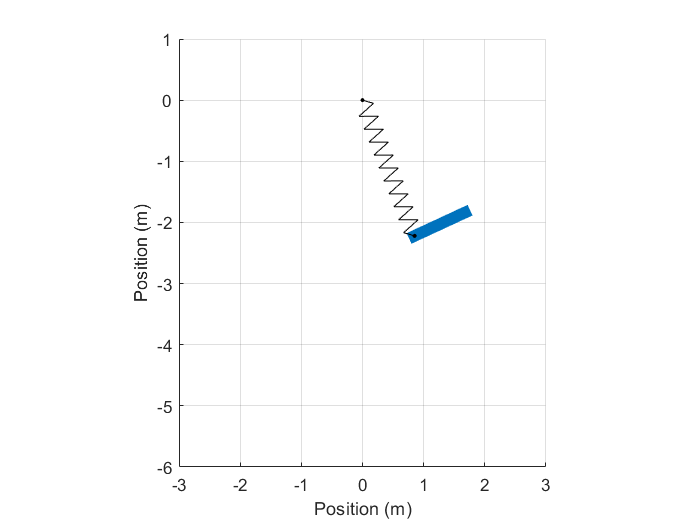

clear
close all
theta = 75;
xg  = -1.2;
yg = -1.4;
 
[t,y] = ode45(@(t,y)stickspring(t,y),linspace(0,40,10000),[xg+0.5*cosd(theta);yg+0.5*sind(theta);deg2rad(theta);0;0;0]);
p = line([y(1,1)-1.2*(cos(y(1,3))./2),y(1,1)+(cos(y(1,3))./2)],[y(1,2)-1.2*(sin(y(1,3))./2),y(1,2)+(sin(y(1,3))./2)],'LineWidth',7,'Color',[0, 0.4470, 0.7410]);
[xs,ys] = spring(0,0,y(1,1)-(cos(y(1,3))./2),y(1,2)-(sin(y(1,3))./2),10,5,0.1);
q = line(xs,ys,'Color','k');
r = rectangle('Position',[-0.025 -0.025 0.05 0.05],'Curvature',[1 1],'FaceColor','k');
s = rectangle('Position',[-0.025+y(1,1)-(cos(y(1,3))./2) -0.025+y(1,2)-(sin(y(1,3))./2) 0.05 0.05],'Curvature',[1 1],'FaceColor','k');
h = gcf;
h.Color = 'w';
axis equal
xlim([-3 3])
ylim([-6 1])
xlabel('Position (m)')
ylabel('Position (m)')
grid on
tic
tr = toc;
while tr <= 30
    tr = toc;
    y1t = interp1(t,y(:,1),tr);
    y2t = interp1(t,y(:,2),tr);
    y3t = interp1(t,y(:,3),tr);
    p.XData = [y1t-1.2*(cos(y3t)./2),y1t+(cos(y3t)./2)];
    p.YData = [y2t-1.2*(sin(y3t)./2),y2t+(sin(y3t)./2)];
    [q.XData,q.YData] = spring(0,0,y1t-(cos(y3t)./2),y2t-(sin(y3t)./2),10,5,0.1);
    s.Position = [-0.025+y1t-(cos(y3t)./2) -0.025+y2t-(sin(y3t)./2) 0.05 0.05];
    drawnow
end

## Activities:

- Define the point where the spring meets the stick as A, and the center of mass of the stick (located in the center of the stick) as G. Assume that the stick is approximately one-dimensional. Define $\vec{r}_A$ as a function of the x-position of the center of mass relative to the origin ($x_G$), the y-position of the center of mass from the origin ($y_G$), and the counter-clockwise angle of the stick from the horizontal ($\theta$). 

- Using linear and angular momentum balancing, find second-order ODE's for $\ddot{x_G}$, $\ddot{y_G}$, and $\ddot{\theta}$.

- Compare the motion of the stick-on-a-spring for two slightly different initial conditions. What do you notice, and why do you think that happens?

function [xs ys] = spring(xa,ya,xb,yb,varargin)
% SPRING         Calculates the position of a 2D spring
%    [XS YS] = SPRING(XA,YA,XB,YB,NE,A,R0) calculates the position of
%    points XS, YS of a spring with ends in (XA,YA) and (XB,YB), number
%    of coils equal to NE, natural length A, and natural radius R0. 
%    Useful for mass-spring oscillation animations.
% USAGE: in a first call in your code, call it with the full parameters.
% Then, only you have to give it the coordinates of the ends.
% EXAMPLE:
% xa = 0; ya = 0; xb = 2; yb = 2; ne = 10; a = 1; ro = 0.1;
% [xs,ys] = spring(xa,ya,xb,yb,ne,a,ro); plot(xs,ys,'LineWidth',2)
%...
% [xs,ys]=spring(xa,ya,xb,yb); plot(xs,ys,'LineWidth',2)
%
%   Made by:            Gustavo Morales   UC  08-17-09 gmorales@uc.edu.ve
%
persistent ne Li_2 ei b
if nargin > 4 % calculating some fixed spring parameters only once time
    [ne a r0] = varargin{1:3};                  % ne: number of coils - a = natural length - r0 = natural radius
    Li_2 =  (a/(4*ne))^2 + r0^2;                % (large of a quarter of coil)^2
    ei = 0:(2*ne+1);                            % vector of longitudinal positions
    j = 0:2*ne-1; b = [0 (-ones(1,2*ne)).^j 0]; % vector of transversal positions
end
R = [xb yb] - [xa ya]; mod_R = norm(R); % relative position between "end_B" and "end_A"
L_2 = (mod_R/(4*ne))^2; % (actual longitudinal extensión of a coil )^2
if L_2 > Li_2
   error('Spring:TooEnlargement', ...
   'Initial conditions cause pulling the spring beyond its maximum large. \n Try reducing these conditions.')
else
    r = sqrt(Li_2 - L_2);   %actual radius
end
c = r*b;    % vector of transversal positions
u1 = R/mod_R; u2 = [-u1(2) u1(1)]; % unitary longitudinal and transversal vectors 
xs = xa + u1(1)*(mod_R/(2*ne+1)).*ei + u2(1)*c; % horizontal coordinates
ys = ya + u1(2)*(mod_R/(2*ne+1)).*ei + u2(2)*c; % vertical coordinates
end

function zdot = stickspring(t,z,p);

rdot = z(4:6);
vdot1 = 5*(-z(1) + cos(z(3))/2);
vdot2 = 5*(-z(2) + sin(z(3))/2) - 9.81;
vdot3 = 6*(z(2)*cos(z(3)) - z(1)*sin(z(3)));

zdot = [rdot;vdot1;vdot2;vdot3];
end